HW 4 Problem 5

part (a)

function fn = myfs(Dn,omega0,t)
%
% fn = myfs(Dn,omega0,t)
% % Evaluates the truncated Fourier Series at times t
%
% Dn -- vector of Fourier series coefficients %
% omega0 -- fundamental frequency
% t -- vector of times for evaluation %
% fn -- truncated Fourier series evaluated at t
    N = (length(Dn) - 1) / 2;
    fn = zeros(size(t));
    for k = -N:N
        Ck = Dn(k + N + 1);
        fn = fn + Ck * exp(1i * omega0 * k * t);
    end
end

part (b)

N = 10;
omega0 = 2 * pi;
kC = 0.5;
nL = -N:1:-1;
nR = 1:1:N;
kL = 1i./(2.*pi.*nL);
kR = 1i./(2.*pi.*nR);
Dn = [kL, kC, kR];
t = -2:0.01:2;
f = myfs(Dn, omega0, t);

subplot(1, 2, 1);
plot(t, f);

xlabel('t');
ylabel('y');

N = 50;
omega0 = 2 * pi;
kC = 0.5;
nL = -N:1:-1;
nR = 1:1:N;
kL = 1i./(2.*pi.*nL);
kR = 1i./(2.*pi.*nR);
Dn = [kL, kC, kR];
t = -2:0.01:2;
f = myfs(Dn, omega0, t);

subplot(1, 2, 2);
plot(t, f);

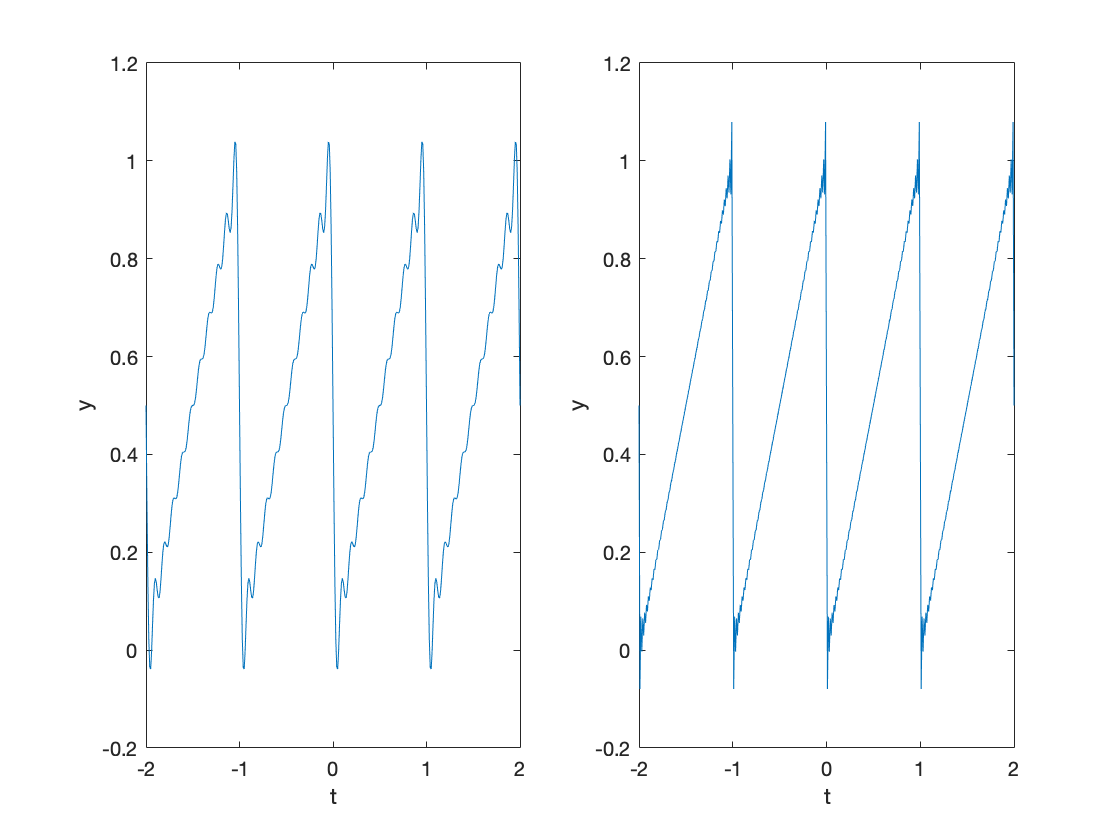

xlabel('t');
ylabel('y');